# MAT 343 Lab 6 - Yuki Ogawa

*NOTE: for this problem you might want to watch the second video in the tutorial videos for this lab. Delete this note upon submission.*

A=imread('gauss.jpg'); %load the picture
B=double(A(:,:,1));  %convert to double precision
B=B/255;             %scale the values of B
[U,S,V]=svd(B);      %compute the SVD decomposition of B
image(A);

## Problem 1

Compute the dimensions of U, S and V

size(U)

ans =    380   380


size(S)

ans =    380   664


size(V)

ans =    664   664


## Problem 2

Compute the best rank-1 approximation and store it in` rank1`

k = 1;
rank1 = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
rank(rank1)

ans = 1

Visualize rank1 by performing steps 3 -6

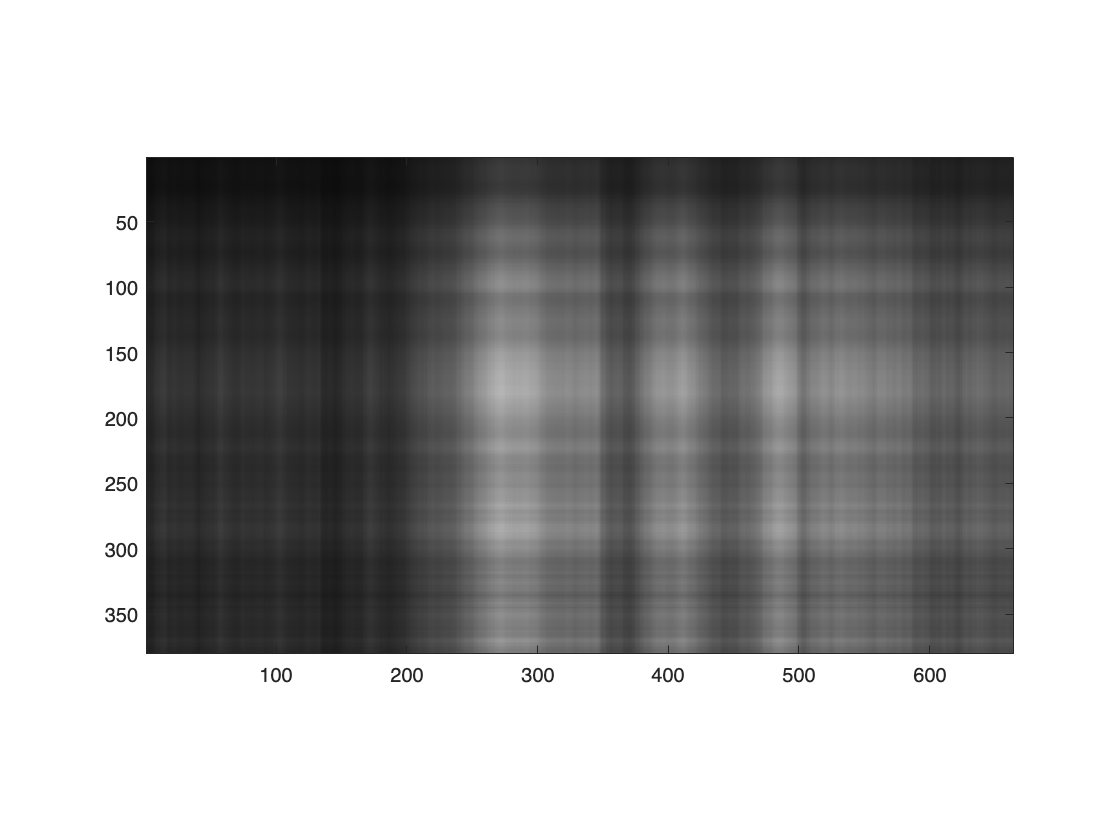

% step 3
C = zeros(size(A));
% step 4
C(:,:,1)  = rank1;
C(:,:,2)  = rank1;
C(:,:,3)  = rank1;
% step 5
C = max(0,min(1,C));
% step 6
image(C), axis image

## Problem 3

Create and view a rank-10 approximation to the original picture

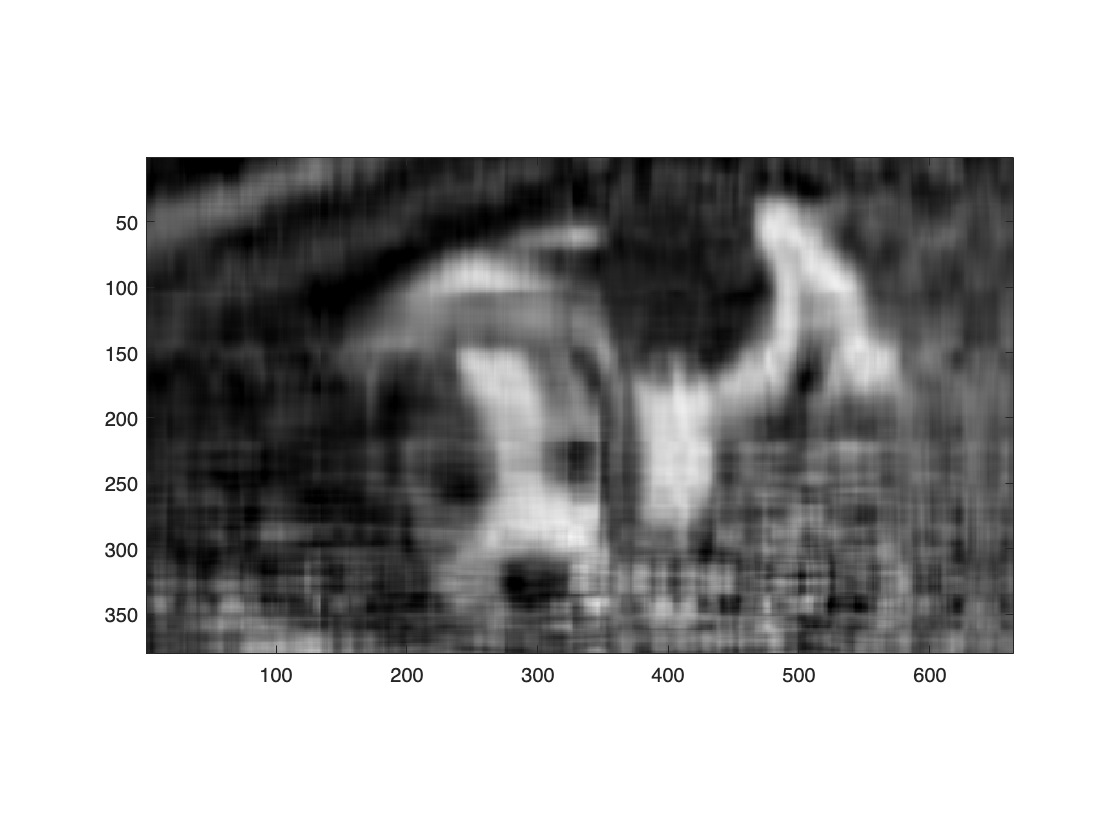

k = 10;

rank1 = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
C(:,:,1)  = rank1;
C(:,:,2)  = rank1;
C(:,:,3)  = rank1;
C = max(0,min(1,C));
image(C), axis image

## Problem 4

Experiment with different ranks until you found one that gives, in your opinion, an acceptable approximation.

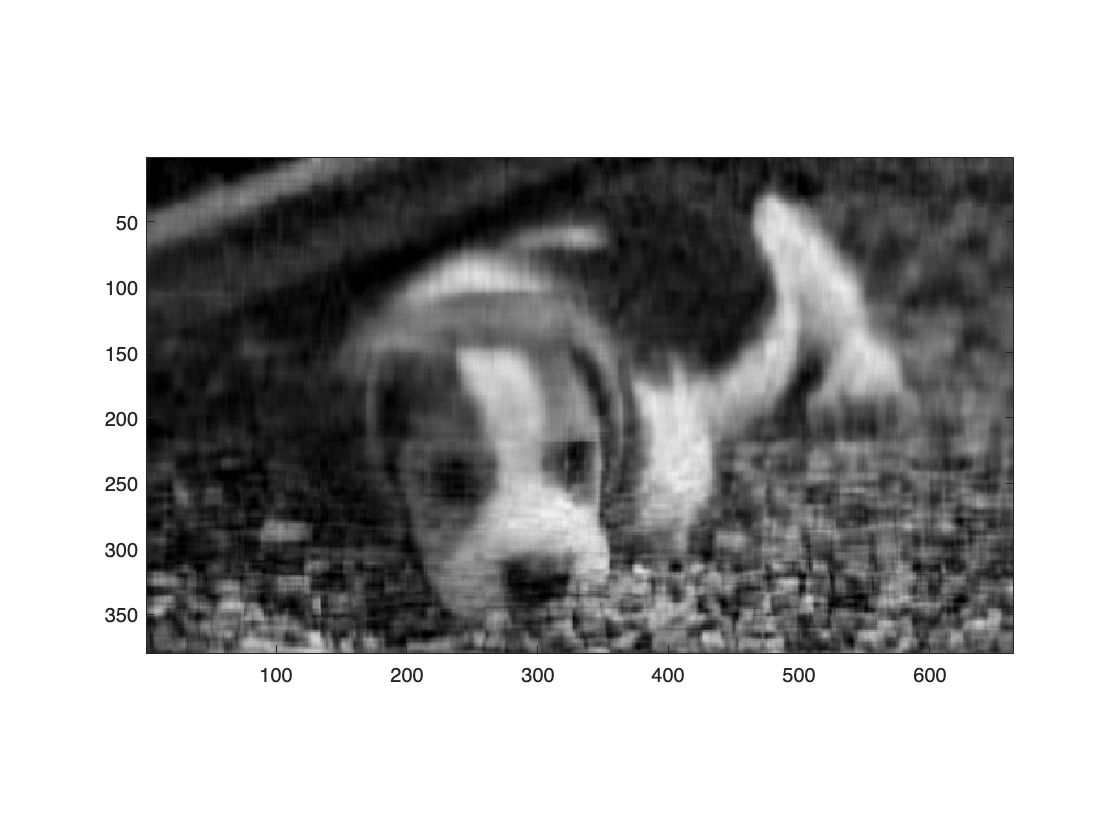

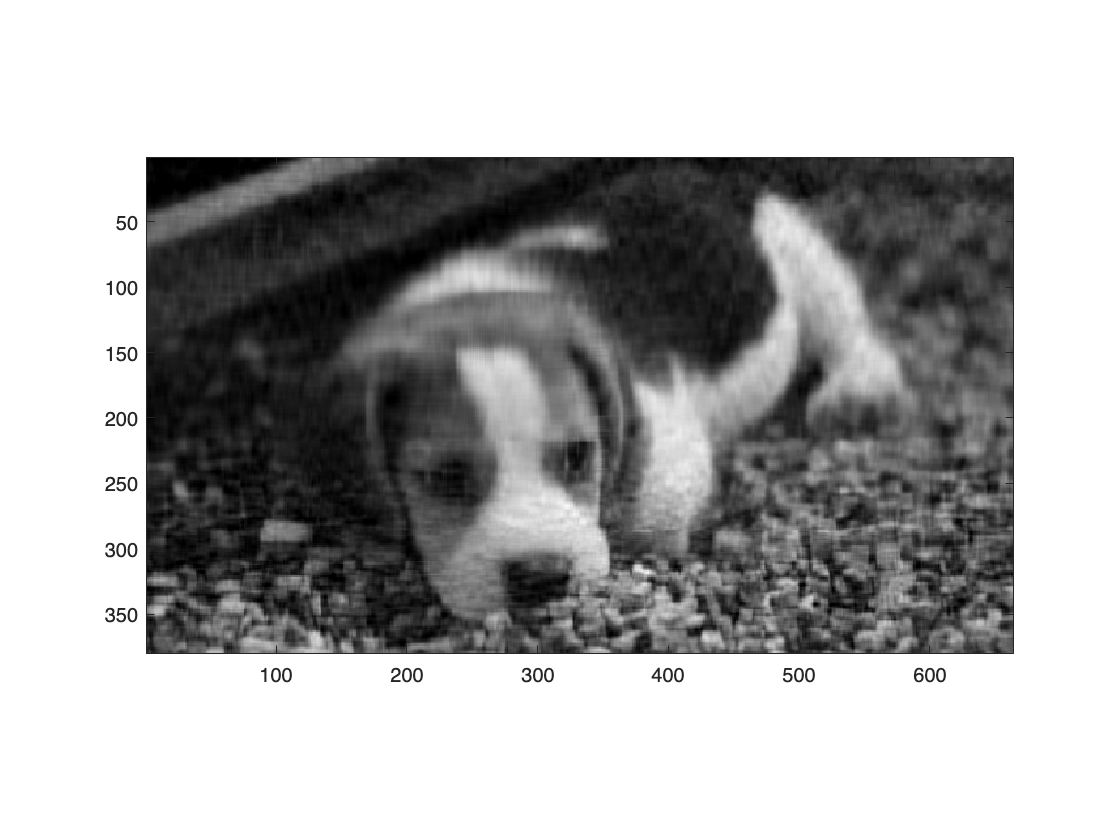

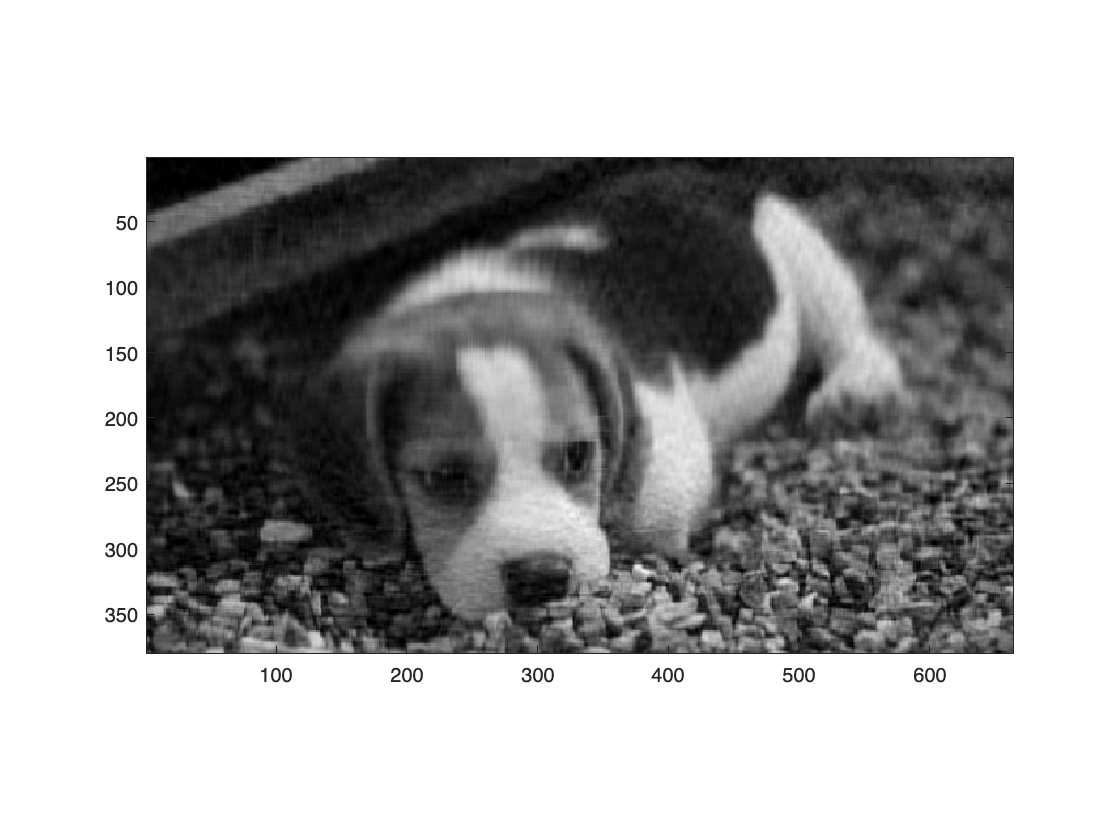

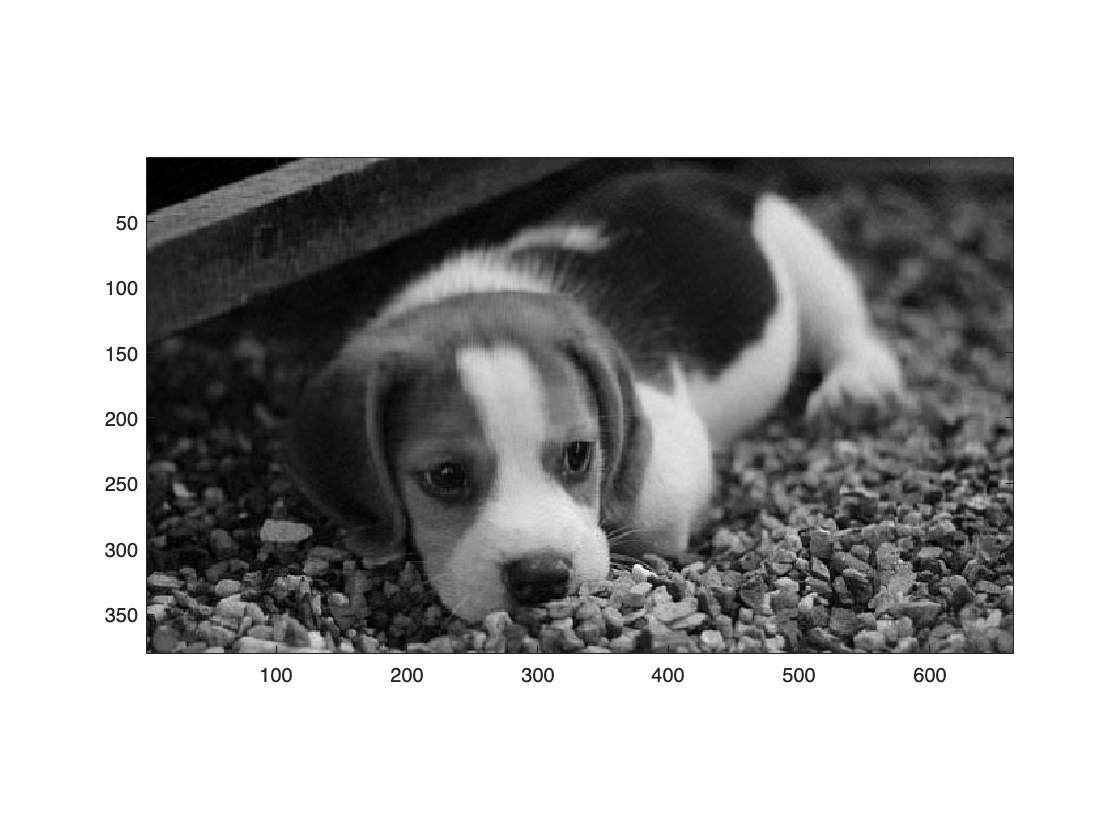

for k=[20 30 40 100]
    rank1 = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
    C = zeros(size(A));
    C(:,:,1)=rank1;
    C(:,:,2)=rank1;
    C(:,:,3)=rank1;
    C = max(0,min(1,C));
    figure(k);
    image(C), axis image
end

## Problem 5

What rank-r approximation exactly reproduces the original picture? Explain,

Answer: 256

This image requires a pure gray scale representaion denoted by 256 bits. 

## Problem 6

### (i)

How much data is needed to represent a rank-k approximation? Explain.

Answer: k(1+m+n)

Ak = S(k,k) + U(:,k) + V(:,k)

Thus, we need k+mk+nk=k(1+m+n) data. 

### (ii)

Find the compression rate for the value of the rank you determined in problem 4. Explain.

Answer: 

the rate (rank k) = k(1+m+n) / 380*664

Assign m=380 and n=664, rate= 1045*k/252320

When

    k = 20, rate = 0.082831

    k = 30, rate = 0.12425

    k = 40, rate = 0.16566

    k = 100, rate = 0.41416

What does the compression rate represent? Explain.

Answer: The compression ratio is the ratio of the data size before compression to the data size after compression when a file is compressed using a compression tool. The higher the rate, the higher the quality of the image. However, when the ratio is more than 1.0, the quality does not change visually. 

## Problem 7

Find the smallest value of k such that the rank-k approximation uses the same or more amount of data as the original picture. Explain how you obtained the answer.

Answer: 242

When the ratio exceeds 1.0, the image needs more data than original one. 

Solve 1045*k > 25230 for k. 

k > 241.45

k must be an integer, so the answer is 242. 